# Training data 

More on [https://github.com/slevin48/gta](https://github.com/slevin48/gta) 

## Data access

### Get images

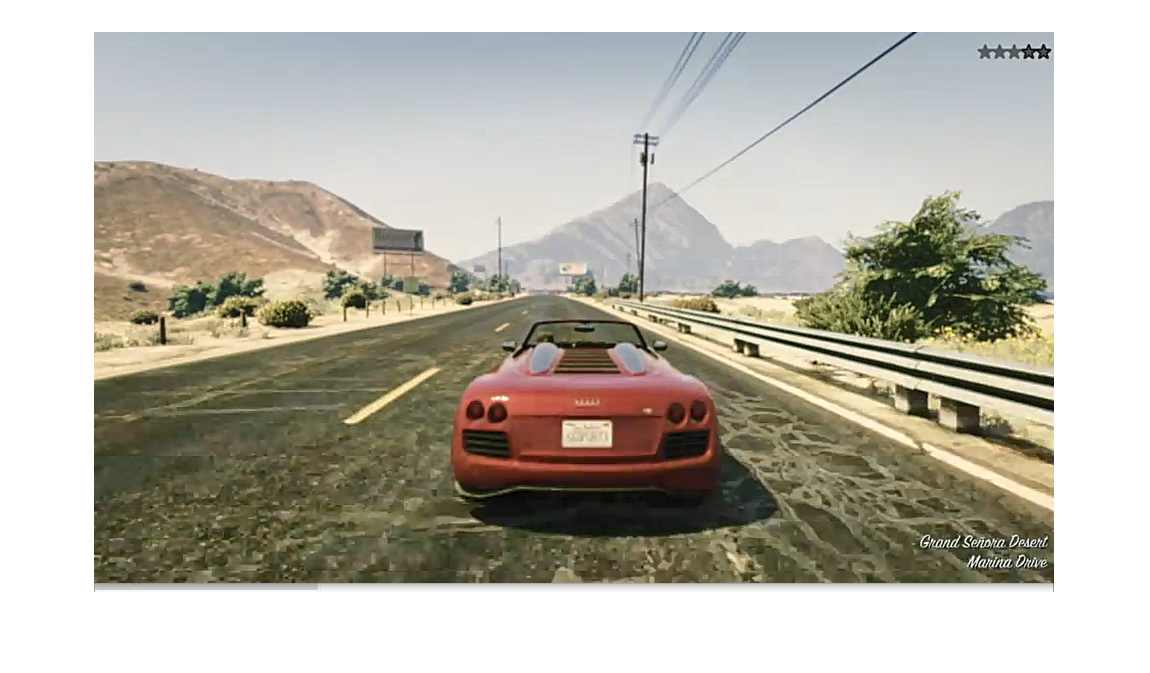

training_dataset = "2021-03-01-2";
training_data_0 = imread("D:\devel\AI-workflow\samples\"+training_dataset+"\img_0.png");
imshow(training_data_0)

length(ls("D:\devel\AI-workflow\samples\"+training_dataset))

ans = 944

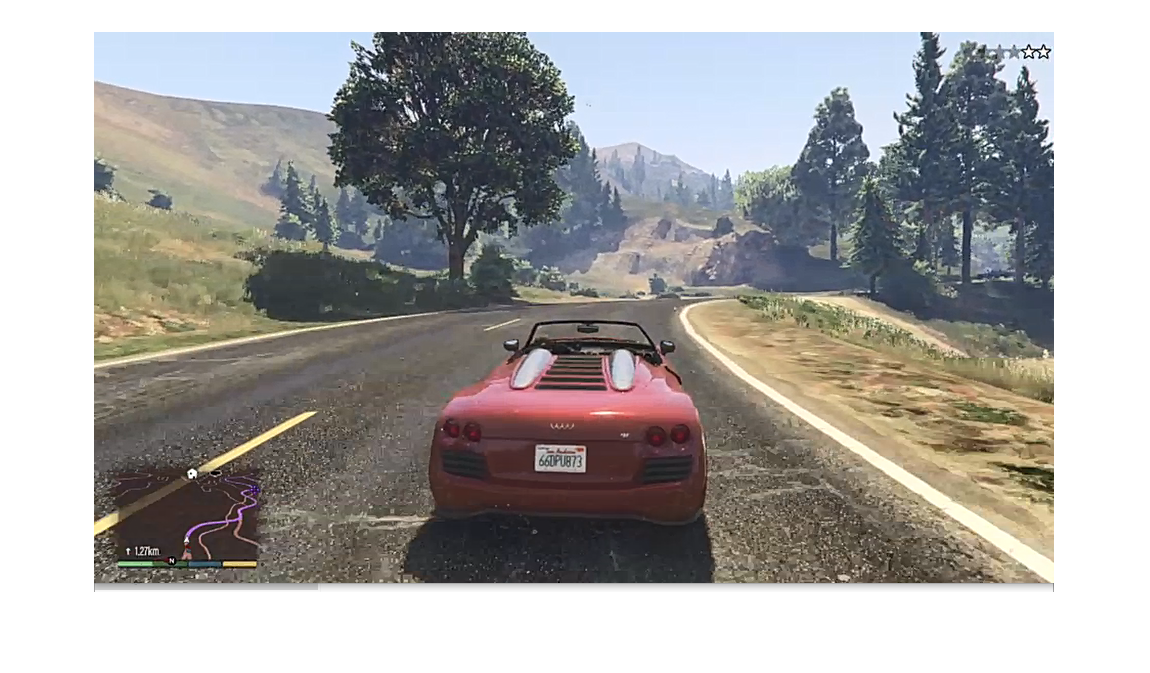

i = 212;
training_img = imread("D:\devel\AI-workflow\samples\"+training_dataset+"\img_"+string(i)+".png");
imshow(training_img)

data = readtable("D:\devel\AI-workflow\samples\"+training_dataset+"\data.csv");
data = renamevars(data,["Var1","Var2","Var3","Var4","Var5","Var6"],["img", "x", "y", "r", "l", "b"]);
data

data = 941×6 table
                    img                        x             y            r       l    b
    ___________________________________    __________    __________    _______    _    _

    {'samples/2021-03-01-2/img_0.png' }     -0.015747             0          0    0    0
    {'samples/2021-03-01-2/img_1.png' }     -0.015747             0          0    0    0
    {'samples/2021-03-01-2/img_2.png' }     -0.015747     0.0078735    0.12891    0    0
    {'samples/2021-03-01-2/img_3.png' }       -0.1496      0.070862    0.99609    0    0
    {'samples/2021-03-01-2/img_4.png' }             0    -0.0078735    0.99609    0    0
    {'samples/2021-03-01-2/img_5.png' }    -0.0078735     -0.023621    0.99609    0    0
    {'samples/2021-03-01-2/img_6.png' }       0.22046     -0.078

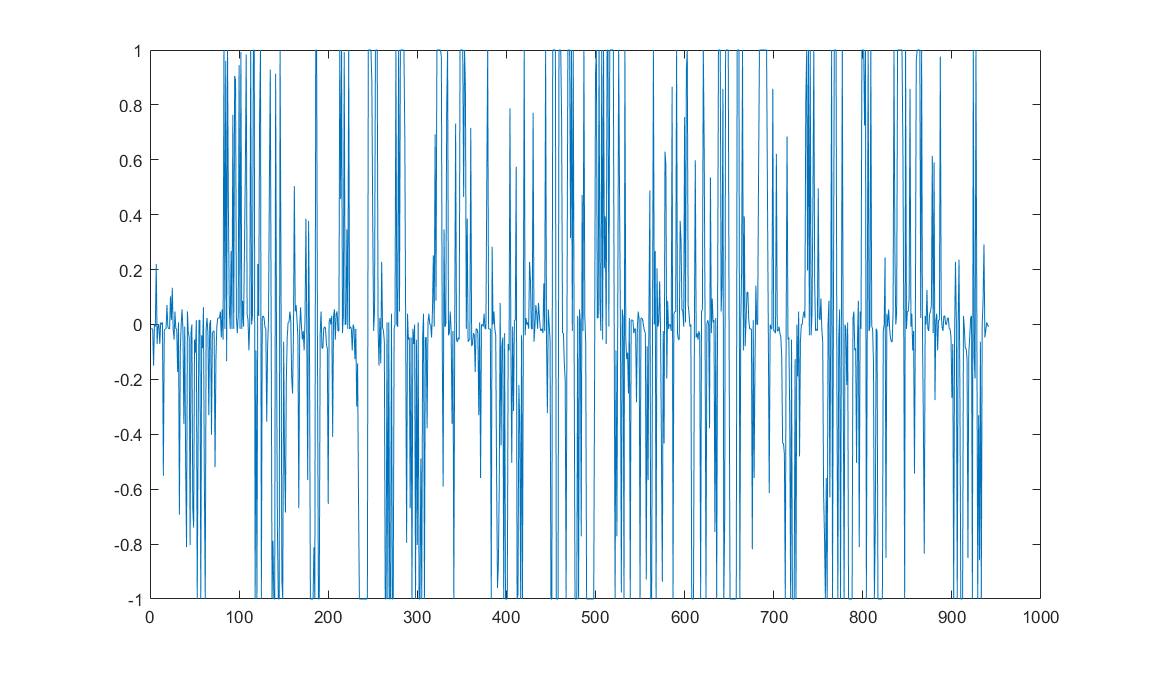

plot(data.x)

### Get data from Numpy directly

pyenv

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\Users\badmo\AppData\Local\Programs\Python\Python39\python.EXE"
          Library: "C:\Users\badmo\AppData\Local\Programs\Python\Python39\python39.dll"
             Home: "C:\Users\badmo\AppData\Local\Programs\Python\Python39"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "17248"
      ProcessName: "MATLAB"


training_dir = uigetdir

training_dir = 'D:\devel\AI-workflow\data'

% training_dataset"training_data-2021-02-12-2"
% training_dir = "training_data\"+training_dataset

npfiles = dir(training_dir+"\*.npy")

npfiles = 2×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


length(npfiles)

ans = 2

npdata = py.training_data.load_data(training_dir+"/X.npy")

npdata =   Python list with no properties.

    [array([[0.40701129, 0.37865122, 0.29349376],
           [0.31666667, 0.30123589, 0.25591206],
           [0.34851456, 0.35433749, 0.29405823],
           [0.36590018, 0.38597742, 0.28354724],
           [0.3840404 , 0.39894236, 0.2885205 ],
           [0.34439097, 0.34327986, 0.26043375],
           [0.35573381, 0.37345811, 0.29399881],
           [0.35876411, 0.37058824, 0.28184789],
           [0.46449198, 0.48158051, 0.35580511],
           [0.41984551, 0.40494355, 0.30286393],
           [0.4778669 , 0.47322638, 0.35013072],
           [0.58135472, 0.57118835, 0.41684492],
           [0.70695187, 0.67557932, 0.46723113],
           [0.69425431, 0.65300059, 0.47745098],
           [0.65244801, 0.61453357, 0.49044563],
           [0.58749851, 0.57272133, 0.4414082 ],
           [0.4732145 , 0.46057635, 0.3579798 ],
           [0.33169935, 0.33562092, 0.27489602],
         

npfile = 3;
% npdata = py.numpy.load("training_data\training_data-"+string(nb_train)+".npy")
% npdata = py.training_data.load_data(training_dir+"/training_data-"+string(npfile)+".npy")
% mdata = cell(npdata)
% imshow(uint8(mdata{1}))

### Browse training data with an app

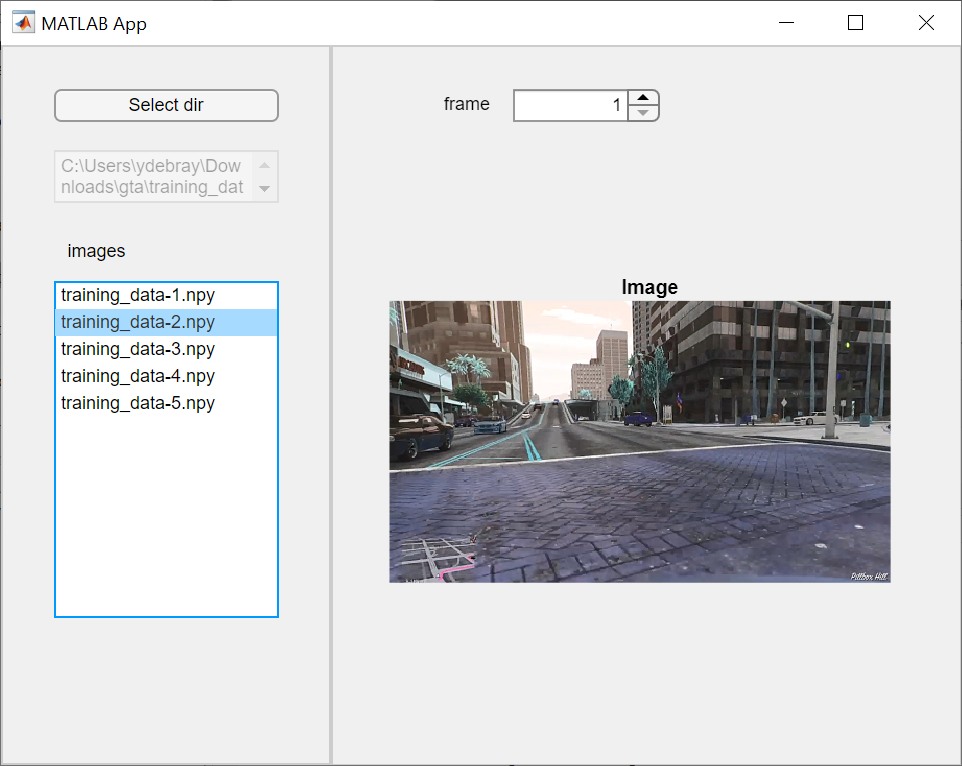

### Specify data

training_dataset = "2021-03-01-4";
dataFolder = "D:\devel\AI-workflow\samples\"+training_dataset;
% renameImages(dataFolder); % only need to be run once
imds = imageDatastore(dataFolder);

## Modelling

### Aside : what does a pre-trained ACF detector give us ?

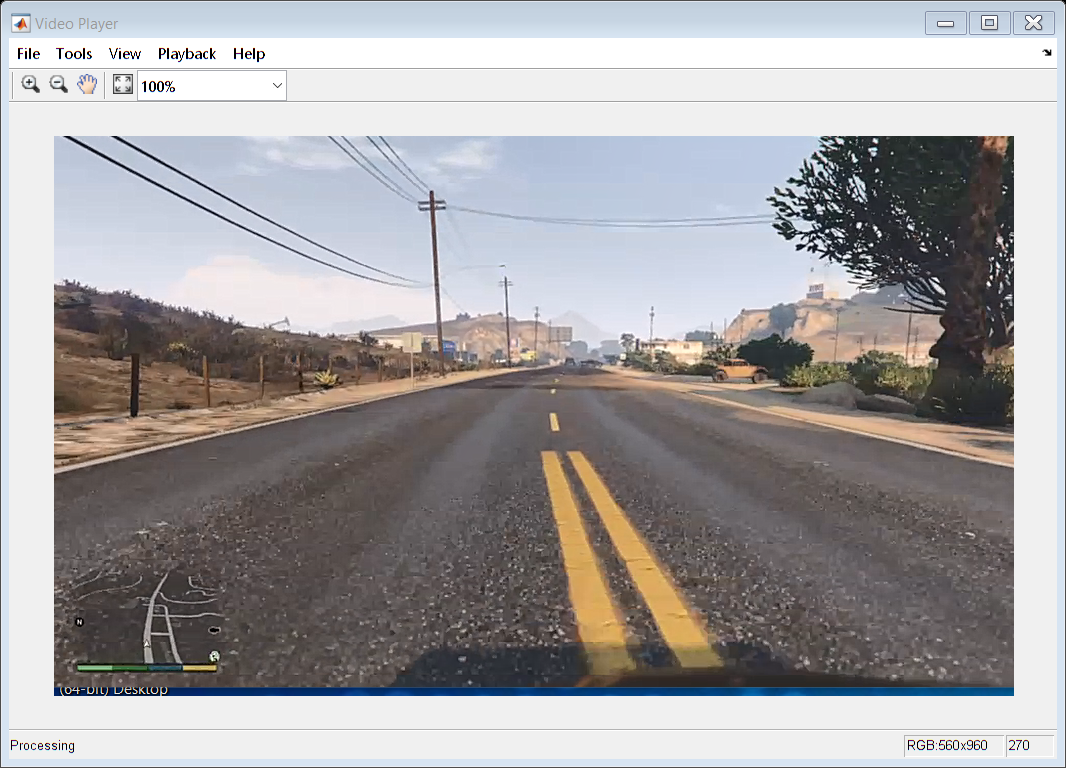

detector = vehicleDetectorACF('front-rear-view');
vp = vision.VideoPlayer ;

reset(imds);
reset(vp)
while hasdata( imds )
    I = read( imds );
    [bboxes,scores] = detect(detector,I);
    if ~isempty( bboxes )
        I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
    end
    step( vp, I )
    drawnow
end 

### Deep Learning

Read in response data and reformat 

training_dataset = "training_data-2021-02-14-1";
sequence = 1;
T = readtable("keyboard/"+training_dataset+"/training_data-"+string(sequence)+".csv");
numPoints = size(T, 1);
right = T.D ;
left = T.Q ;
straight = double(~( logical( right) | logical(left) ));
labels = straight + 2*left + 3*right; 
% onehotencode()
imds.Labels = categorical(labels);

Resize input data to match network architecture

outputSize = [270 480];
auimds = augmentedImageDatastore(outputSize, imds);

### Use Deep Network Designer to do transfer learning

In this case, using AlexNet for transfer learning does not work as the training is not converging. We need more data, and also to revisit how the problem is formulated. 

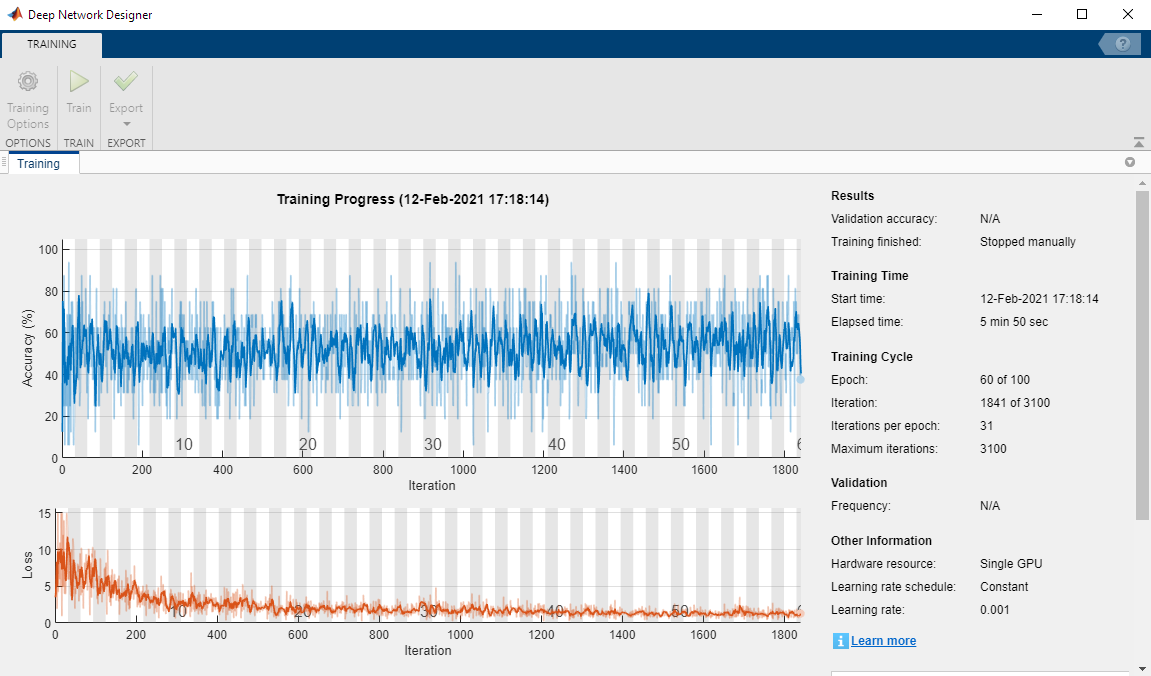

### Helper function

function renameImages( dataFolder )

D = dir(dataFolder);
nameRoot = "training_data_";
for i = 1:numel(D)
    if D(i).isdir == 0
        
        I = imread(fullfile(dataFolder, D(i).name));
        [~,filename,ext] = fileparts(D(i).name);
        nameLength = length( filename );
        if nameLength == 17
            continue;
        else
            if nameLength == 15
                imNumber = ["00" + filename(15)] ;
            elseif nameLength == 16
                imNumber = ["0" + filename(15:16)];                
            end
            newFilename = [nameRoot + imNumber + ext];
            imwrite(I, fullfile(dataFolder, newFilename));
            delete(fullfile(dataFolder, D(i).name));
        end
    end
end

end